### 初始化

clc;
clear

### 参数设置

M = 500000;
Fs = 10E6;
% pathname = 'Data\Instrument_Capture_2023_761k_2.csv';
pathname = 'Capture_BP_26 Oscilloscope - Waveform Data_500K.csv'

pathname = 'Capture_BP_26 Oscilloscope - Waveform Data_500K.csv'

% pathname = 'Noise.csv';   
% Single-End

### 数据读取

range_index_head = ['A' num2str(11)];   
range_index_tail = ['A' num2str(10+M)];

% range_index_head = ['B' num2str(2)];   
% range_index_tail = ['B' num2str(2+M-1)];

range_index = [range_index_head ':' range_index_tail];
wave_data = readmatrix(pathname,"Range",range_index);
vout = wave_data(:,1);

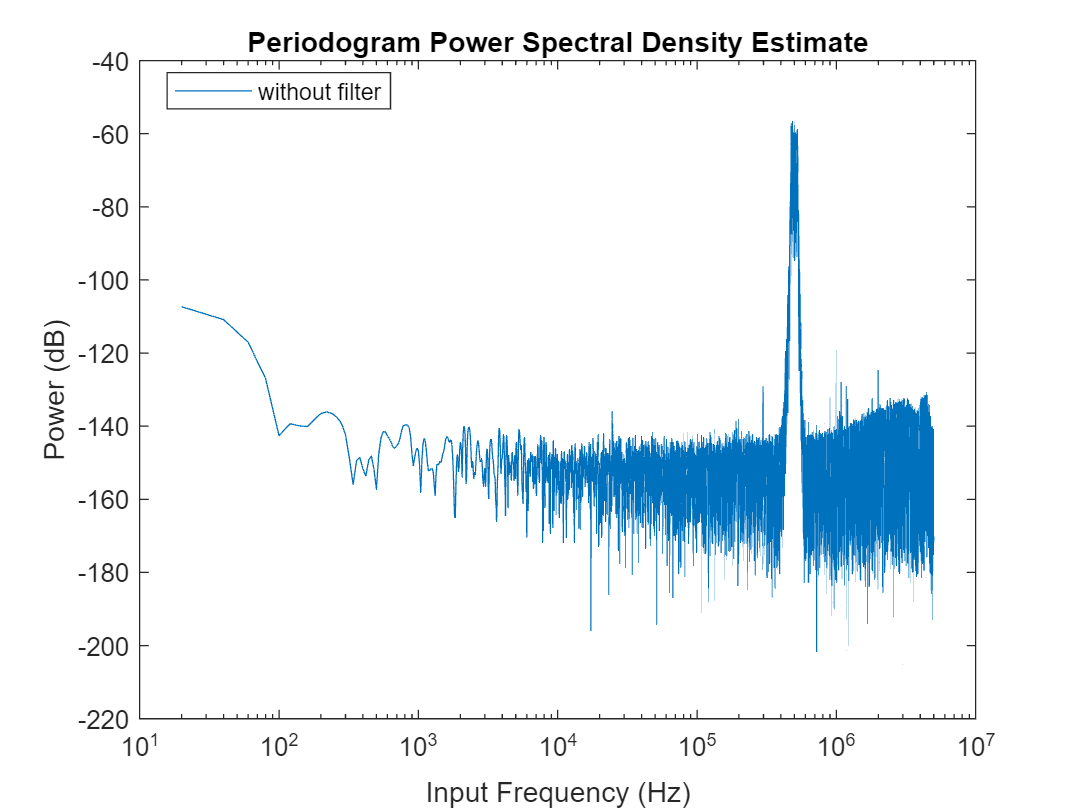

[pxx, f] = periodogram(vout, kaiser(M,38), M, Fs, "onesided", "power");
figure("Name",'FFT')
% semilogx(f, pow2db(pxx_Noise));
% grid on;
% hold on
semilogx(f, pow2db(pxx));

title("Periodogram Power Spectral Density Estimate");
xlabel("Input Frequency (Hz)");
ylabel("Power (dB)")
legend({'without filter','with filter (FO=500Khz)'}, 'Location',"best")

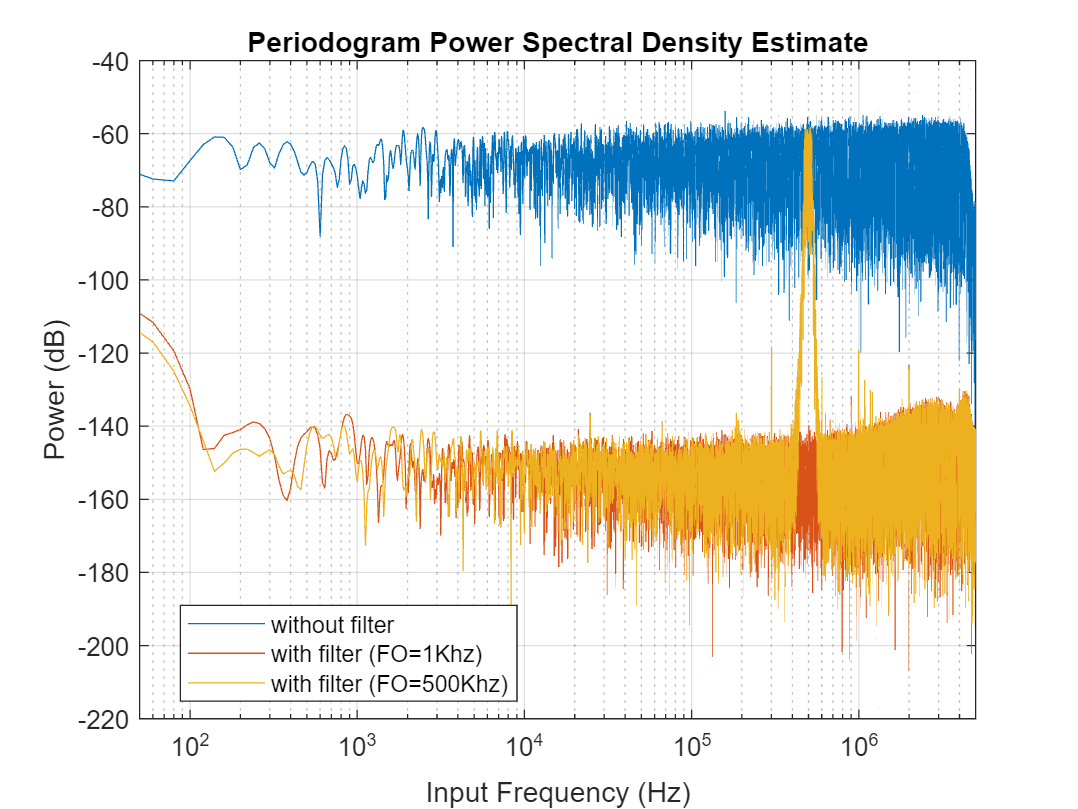

load("pxx_data.mat")

p = [pxx_noise, pxx_1k, pxx_500k];

figure()
semilogx(f, pow2db(p));
xlim([50, 5E6])
grid on;
title("Periodogram Power Spectral Density Estimate");
xlabel("Input Frequency (Hz)");
ylabel("Power (dB)")
legend({'without filter','with filter (FO=1Khz)','with filter (FO=500Khz)'}, 'Location',"best")

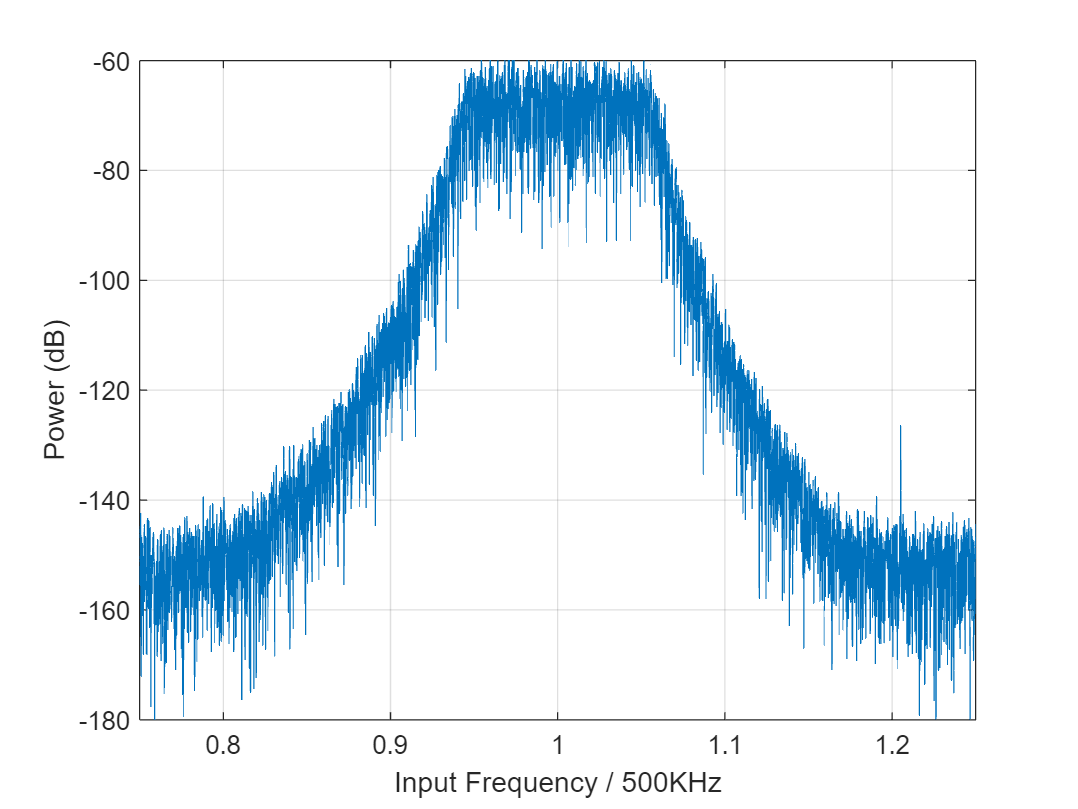

figure()
plot(f./500E3, pow2db(pxx_500k));
grid on
xlim([0.75 1.25])
ylim([-180 -60])
xlabel("Input Frequency / 500KHz");
ylabel("Power (dB)")